# 10. 線形フィルタによるノイズ除去

clear;
clf;
getd = @(p)path(p,path);
getd('toolbox_signal/');
getd('toolbox_general/');
rng('default');

## 線形ガウシアンフィルタによるノイズ除去

線形フィルタによるノイズ除去は，ノイジーな画像 $\mathbf{v}$ に平滑化フィルタ $\mathbf{h}$ を畳み込むことで実現される．

2次元フィルタと画像の畳込みは，2次元フーリエ変換を介すことで効率的に計算できる．詳細は3年次の「信号とシステム」「ディジタル信号処理」で詳しく説明するが，畳込みは、周波数空間（フーリエ変換領域）において積として表現される．

今回は，「3. 画像の線形フィルタリング」で用いた関数 "perform_convolution" を用いずに，以下のように2次元配列 $\mathbf{a}, \mathbf{b}$ のフーリエ変換を介した畳込み処理を無名関数として定義する．

% aを空間領域の画像，bを空間領域のフィルタとして，両者の2次元DFTの要素ごとの積を取る
cconv = @(a,b)real(ifft2( fft2(a).*fft2(b) ));

具体的な平滑化フィルタとして，標準偏差 $\mu$ の[ガウシアンフィルタ](https://jp.mathworks.com/help/images/ref/imgaussfilt.html)を考える．

name = 'house';
u = load_image(name,[]);
u = u/255;
n = length(u);
N = n^2;

normalize = @(h)h/sum(h(:));
t = -n/2:n/2-1;
[Y,X] = meshgrid(t',t'); % 中心が0の画像サイズのグリッド（座標が格納された配列データ）を生成
h = @(mu)normalize( exp( -(X.^2+Y.^2)/(2*mu^2) ) ); % muを入力としてnxn画素の画像用のガウシアンフィルタを生成する関数

$\mu=5$ のガウシアンフィルタとそのフーリエ変換を表示する．

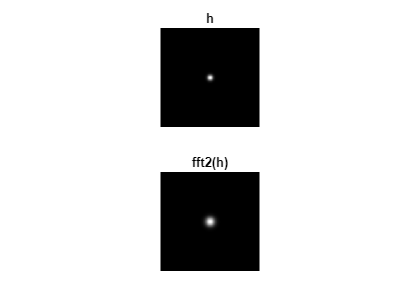

mu = 5;
figure;
subplot(2,1,1);

%ガウシアンフィルタのフィルタ係数を可視化（中心が注目画素に対する重み）
imageplot( h(mu) ); axis('tight');
title('h');
subplot(2,1,2);

%ガウシアンフィルタのフーリエ変換を可視化（ガウス関数のフーリエ変換はガウス関数となる）
% imageplot( fftshift( real(fft2(fftshift(h(mu)))) ) ); axis('tight');
imageplot(fftshift( abs(fft2(h(mu))) )); axis('tight');
title('fft2(h)');

クリーンな画像に擬似的にノイズ（ガウス性ノイズ）を付加し，畳み込み処理 cconv を用いてガウシアンフィルタによるノイズ除去処理を行う．

sigma = 0.1;
v = u + randn(n,n)*sigma;

denoise = @(x,mu)cconv(fftshift(h(mu)), x);

ノイズ除去された復元画像を表示する．

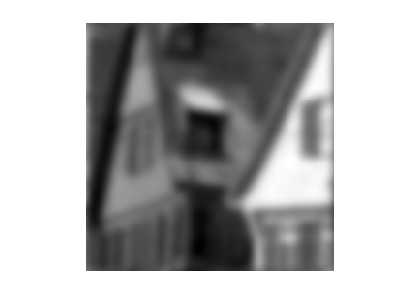

figure;
imageplot( denoise(v,mu) );

## **演習問題**

**演習8-1**: グレースケール画像'house'を読み込み，$\sigma=0.1$ のガウス性ノイズを付加した上で，$\mu$ を $(0.5, 1.5, 3, 4.5, 6, 9)$ と変化させたときのノイズ除去結果とPSNR [dB] を $2\times 3$ のグリッドに表示せよ．

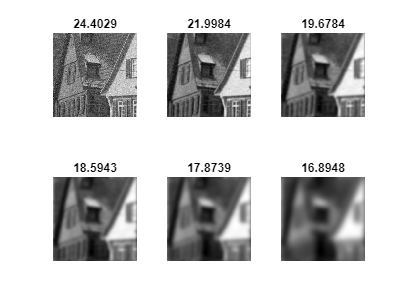

name = 'house';
u = load_image(name,[]);
u = u/255;
n = length(u);
N = n^2;

sigma = 0.1;
v = u + randn(n,n)*sigma;
figure;

mu_list = [0.5, 1.5, 3, 4.5, 6, 9];

for i = 1:6
    subplot(2,3,i);
    mu = mu_list(i);

    normalize = @(h)h/sum(h(:));
    t = -n/2:n/2-1;
    [Y,X] = meshgrid(t',t'); % 中心が0の画像サイズのグリッド（座標が格納された配列データ）を生成
    h = @(mu)normalize( exp( -(X.^2+Y.^2)/(2*mu^2) ) ); % muを入力としてnxn画素の画像用のガウシアンフィルタを生成する関数

%ガウシアンフィルタのフーリエ変換を可視化（ガウス関数のフーリエ変換はガウス関数となる）

    denoise = @(x,mu)cconv(fftshift(h(mu)), x);
    imageplot( denoise(v,mu) ,psnr(u, denoise(v,mu)));
end

**演習8-2**: グレースケール画像'house'を読み込み，$\sigma=0.05, 0.1, 0.2$ のガウス性ノイズを付加した3種類の観測画像を生成する．その上で，それぞれの観測画像に対し，

- 横軸を $\mu$ とし、 $[0.1, 2]$ の範囲で $0.1$ 刻みに $\mu $ を変化させながら復元画像 $\mathbf{u}_r$ を求め，縦軸に $\mu$ の関数として PSNR [dB] をプロットせよ（各観測画像に対応する３つの曲線がプロットされることになるので、legend をつけるように）．

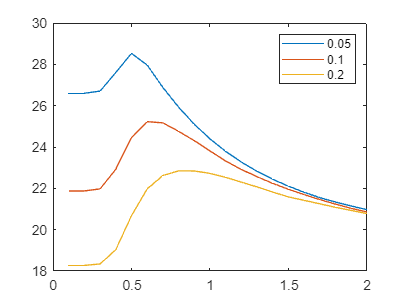

sigma_list = [0.05, 0.1, 0.2];

mu_list = 0.1:0.1:2;
mu_length = length(mu_list);

psnr_list = [];
for i = 1:3
    sigma = sigma_list(i);
    v = u + randn(n,n)*sigma;
    
    for j = 1:mu_length
        mu = mu_list(j);
        psnr_list(end+1) = psnr(u, denoise(v, mu));
    end
end

figure;
plot(mu_list, reshape(psnr_list,[20,3]).');
legend('0.05','0.1', '0.2');

-  各 $\sigma$ において，$\mu$ を変化させた際にPSNRが最大となる（つまり，最も原画像と近く）ような $\mu$ を見つけ，観測画像（$\sigma$ の値をタイトルに表示すること）および最適な $\mu$ を用いたノイズ除去結果（最適な $\mu$ の値と PSNR [dB] をタイトルに表示すること）を $2\times 3$ のグリッドに表示せよ（上段：3種類の観測画像、下段：それぞれの観測画像に対応する復元画像）．※ **PSNR が最大となる **$\mu$** は（目視ではなく）プログラムを用いて見つけること．**

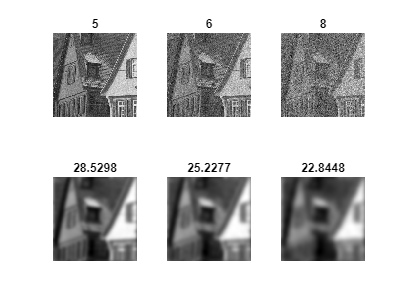

figure;

[max_psnr, index] = max(reshape(psnr_list,[20,3]));

for i = 1:3
    sigma = sigma_list(i);
    v = u + randn(n,n)*sigma;

    mu = index(i);
    subplot(2,3,i);
    imageplot(v,mu);
    subplot(2,3,i+3);
    imageplot(denoise(v, mu),max_psnr(i))
end